# EE525 - Lab Project 1

Authors: Grant Gallagher

Due: 10/8/2021

Objective:

## Initialization

This section of code is used to clear the workspace of all variables and figures, so that the program can be run from scratch.

clc;    % Clear command window
clear;  % Clear all variables from workspace
clf;    % Clear all figures

## 1. Digital Communications

### 1.1 Introduction

In a phase-shift keyed (**PSK**) digital communication system,  a binary digit (also termed a bit), which is either a “**0**” or a “**1**”, is communicated to a receiver by sending either$\;s_0 =\mathrm{Acos}\left(2\pi F_0 t+\pi \;\right)$ to represent a “0” or $s_1 =\mathrm{Acos}\left(2\pi F_0 t\;\right)$ to represent a “1”, where $A>0$. The receiver that is used to decode the transmission is shown in the figure below. The receiver that is used to decode the transmission is shown in the figure below. 

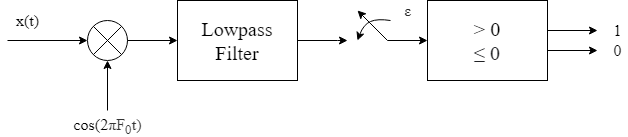

For this system, it is desired to send a signal of "0" or "1" to the receiver, which will then output a true binary value of 0 or 1. The input signal to the system is the noise corrupted signal which can be modeled by the following equation


$$x\left(t\right)=s_i \left(t\right)+w\left(t\right)$$


where $w\left(t\right)$ represents the channel noise and $s_i \left(t\right)$ represents a desired signal of either "0" or "1". Thus, the total input to the system can be represented by the sum of the two signals. 

Once the reference signal, $x\left(t\right)$, is sent to the receiver, it is multiplied by a constant periodic waveform of the same frequency, $\mathrm{cos}\left(2\pi F_0 t\right)$, and is passed through a lowpass filter. The result is a magnitude value which is proportional to the amplitude of the input signal. For example, it is desired to send a "1" to the system without any considering any channel noise,


$$\zeta ={\left\lbrack s_1 \left(t\right)\left(\mathrm{cos}\left(2\pi F_0 t\;\right)\right)\right\rbrack }^{\mathrm{LPF}}$$


Then, we substitute the analog expression for $s_1 \left(t\right)$ as,

   
$$\zeta ={\left\lbrack \mathrm{Acos}\left(2\pi F_0 t\;\right)\mathrm{cos}\left(2\pi F_0 t\;\right)\right\rbrack }^{\mathrm{LPF}}$$


and taking the product of the terms results in

 
$$\zeta ={\left\lbrack {\mathrm{Acos}}^2 \left(2\pi F_0 t\right)\right\rbrack }^{\mathrm{LPF}}$$


Next, we can apply the identity of ${\mathrm{cos}}^2$ to give us


$$\zeta ={\left\lbrack \frac{A}{2}\left(1-\mathrm{cos}\left(4\pi F_0 t\right)\right)\right\rbrack }^{\mathrm{LPF}}$$


and pull out the constant term


$$\zeta ={\frac{A}{2}\left\lbrack 1-\mathrm{cos}\left(4\pi F_0 t\right)\right\rbrack }^{\mathrm{LPF}}$$


which results in a final value of 


$$\zeta =\frac{A}{2}$$


It can also be shown that a "0" input signal will result in $\zeta =-\frac{A}{2}$ since the phase of the input signal is offset by 180°. Subsequently, It can be shown that in the absence of noise, the output of the lowpass filter is,


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2} & \mathrm{for}\;a\;"0"\\
\frac{A}{2} & \mathrm{for}\;a\;"1"
\end{array}\right.$$


 To model the channel noise, we assume that the input to the receiver is the sum of the input signal and the channel noise. By the principle of superposition, we can determine that the actual value of $\zeta$ observed is


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2}+W & \mathrm{for}\;a\;"0"\\
\frac{A}{2}+W & \mathrm{for}\;a\;"1"
\end{array}\right.$$


where $W$ is the Gaussian random variable, $W~N\left(0,1\right)$. This means the the random variable, $W$, follows a Guassian distribution and has mean of 0 with a standard deviation of 1. After all this, the receiver decides if a "1" was transmitted if $\zeta >0$ and a "0" was transmitted if $\zeta \le 0$. The problem with this model is that the output signal may not coincide witht the desired input signal. If a "1" is sent, the channel noise can disrupt the signal noise causing the output value to be flipped to a "0". The objective of this exercise is to analyze the probability of error, $P_e$, as a function of the input signal amplitude, $A$, using analytical and numerical methods.

### 1.1 Analytical Solution

In order to determine the probability of an error, we need to determine the probability of each instance. To do this, we must consider the conditional probabilities of error using Bayes' Theorem, which states that

   
$$P\left(A|B\right)=\frac{P\left(B|A\right)P\left(A\right)}{P\left(B\right)}$$


In this case, we want to identify the probability that error occurs, given the probability that a bit is sent. Thus, the probability that an error occurs when a "0" is sent can be represented by,


$$P_{e,0} =P\left(\mathrm{error}|0\right)P\left(0\right)$$


where the probability of a "0" being sent is 0.5. Likewise, the probability that an error occured when a "1" is sent can be represented by,


$$P_{e,1} =P\left(\mathrm{error}\left|1\right.\right)P\left(1\right)$$


where the probability of a "1" being sent is 0.5. Thus the total probability that an error occurs is equal to the sum of the total probabilities


$$P_e =P\left(\mathrm{error}\left|0\right.\right)P\left(0\right)+P\left(\mathrm{error}\left|1\right.\right)P\left(1\right)$$


To start, we can determine that


$$P\left(0\right)=P\left(1\right)=0\ldotp 5$$


because the sum of the total possibilities must add up to 1.

P_0 = 0.5; % Probability that a "0" is sent
P_1 = 0.5; % Probability that a "1" is sent

Next, we must calculate the conditional probabilities of error. Since $W$ is a Normal Guassian random variable, it's [*Probability Density Function*](https://en.wikipedia.org/wiki/Probability_density_function) (PDF) can be described by the following equation


$$f_X \left(x\right)=\frac{1}{\sqrt{2\pi \;}}e^{-\frac{x^2 }{2}}$$


which is called the Normal Gaussian Probability Density function. Subsequently, we can substite and substitute our receiver value, $\zeta$, for $X$ since the distribution of the random variable it is described by, $W$, is also a Normal Guassian random variable. In this cause, the mean of the input signal is shifted by either $\frac{A}{2}$ or $-\frac{A}{2}$ depending on which bit is being sent. Thus, the PDF can be rewritten as


$$f_X \left(x\right)=\frac{1}{\sigma \sqrt{2\pi \;}}e^{-\frac{{\left(x-\mu \;\right)}^2 }{2}}$$


where $\mu \;$ is the mean of the distrubition ($\pm \frac{A}{2}$), and $\sigma \;$ is the standard deviation of the distribution, which still remains as 1. Substituting these values into our PDF results in


$$f_{Z\;,0} =\frac{1}{\sqrt{2\pi \;}}e^{-\frac{{\left(w+\frac{A}{2}\right)}^2 }{2}} ,\;\;\;\;\;\mathrm{for}\;\mathrm{a}\;\mathrm{"0"}$$


for a "0" being sent, and


$$f_{Z,1} =\frac{1}{\sqrt{2\pi \;}}e^{-\frac{{\left(w-\frac{A}{2}\right)}^2 }{2}} ,\;\;\;\;\;\mathrm{for}\;\mathrm{a}\;\mathrm{"1"}$$


These two functions represent the new probability density functions for $\zeta$ for when a "0" or "1" is sent, respectively. The probability density function (PDF) is a function whose value at any given sampe in the sample space can be interpreted as providing the relative likelihood that the value of the random variable would be close to that sample. 

syms A W zeta
Guass_Norm_pdf = 1/sqrt(2*pi) * exp((-(zeta)^2)/2); % Normal Gaussian Distribution func.
Zeta_0_pdf = subs(Guass_Norm_pdf, zeta, (W + A/2)); % PDF of a "0" being read
Zeta_1_pdf = subs(Guass_Norm_pdf, zeta, (W - A/2)); % PDF of a "1" being read

Subsequently another important function can be derive from the PDF. The [*Cumulative Distribution Function*](https://en.wikipedia.org/wiki/Cumulative_distribution_function) (CDF) is the probability that the random variable takes a value less than or equal to $x$, such that


$$F_X \left(x\right)=P\left\lbrace X\le x\right\rbrace$$


The CDF relates to the PDF of a random variable in that they have an integral/derivative relationship. That is, the integral of the PDF is equal to the CDF such that


$$F_X \left(a\right)=\int_{-\infty \;}^a f_X \left(x\right)\mathrm{dx}$$


where $F_X \left(a\right)$ is the CDF evalutate at real value $a$. Additionally, the CDF has one important characteristic in that the minimum and maximum values range from 0 to 1. This means, that the integral (or area under the curve) of the PDF is equal to exactly one,


$$1=\int_{-\infty \;}^{\infty \;} f_X \left(x\right)\mathrm{dx}$$


This property makes sense, since the total sum of probabilities within the sample space must add up to 1.

With regard to problem at hand, we can determine the likelood of an error occuring by evaluating the CDF of the random variable for each case where the sent bit is equal to "0" and "1". In this case, we are calculating the probability of error given a conditioning event. Thus, we can derive the equation of the probability of error given that a "0" was sent as the intregral of the PDF for all values where the read bit iz greater than 0. That is,


$$P\left(\mathrm{error}\left|0\right.\right)=\int_0^{\infty \;} f_{Z,0} \left(\zeta \;\right)d\zeta$$


where the upper and lower bounds of the integral represent the bounds for the probability of where the read bit is equal to "1" (when it should have been "0"). We can then substitute in our PDF function for $f_{Z,0} \left(\zeta \;\right)$,


$$P\left(\mathrm{error}\left|0\right.\right)=\int_0^{\infty \;} \frac{1}{\sqrt{2\pi \;}}e^{-\frac{{\left(w+\frac{A}{2}\right)}^2 }{2}} \mathrm{dw}$$


where $W$ is the only random variable. This may be confusing, however, A can be considered as a simple constant - making $W$ the only random variable we integrate with respect to. Subsewwuently, we can rearrange the terms to remove the constants from the integral, and also rearrange the exponent of the power term to all be within the square,


$$P\left(\mathrm{error}\left|0\right.\right)=\left(\frac{1}{\sqrt{2\pi \;}}\right)\int_0^{\infty \;} e^{-{\left(\frac{w+\frac{A}{2}}{\sqrt{2}}\right)}^2 } \mathrm{dw}$$


The reason why we rearrange the exponent term of the equation is to give it the similar form of the [*Error Function*](https://en.wikipedia.org/wiki/Error_function) (erf). The error function has the following form,


$$\mathrm{erf}\left(z\right)=\frac{2}{\sqrt{\pi }}\int_0^{z\;} e^{-t^2 } \mathrm{dw}$$


Translating the integral in to the respective error function form then yeilds


$$P\left(\mathrm{error}\left|0\right.\right)=\left(\frac{1}{\sqrt{2\pi \;}}\right){\left\lbrack \left(\frac{\sqrt{\pi }}{\sqrt{2}}\right)\mathrm{erf}\left(\frac{{\left(\frac{A}{2}+W\right)}}{\sqrt{2}}\right)\right\rbrack }_0^{\infty }$$


which has the same integration bounds as our original integral. Next, the coefficients infront of the error function can be move outside of the brackets, and the upper and lower bounds can be applied to reach the final closed-form solution,


$$P\left(\mathrm{error}\left|0\right.\right)=\left(\frac{1}{2}\right)\left\lbrack 1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack$$


which represents the probability of error, $P_0$, as a function $A$ given that a "0" was sent to the receiver. The conditional probability as a function of $A$ for a sent bit of "0" can be derived similarly as well. The differences in steps will be that the mean of the density function will negative, and the bounds of integration will be from $-\infty$ to $0$. Incoincidentally, the probability of error as a function of $A$ given that the sent bit is "1" is exactly equal to that for the case where the sent bit is a "0",


$$P\left(\mathrm{error}\left|1\right.\right)=\left(\frac{1}{2}\right)\left\lbrack 1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack$$


Mathematically, we can acheive these results; however, this makes sense due to the face the both density functions are mirrored about the y-axis (zero) and share the same standard deviation. Thus, the likelihood of bad bits for each case is equal, given the same signal amplitude $A$.

P_e_given_0 = int(Zeta_0_pdf,W,0,inf); % CDF of an error given a "0"
P_e_given_1 = int(Zeta_1_pdf,W,-inf,0);     % CDF of an error given a "1"

Finally, the analytical solution to the total probability of error as a function of A can be expressed as


$$P_e =P\left(\mathrm{error}\left|0\right.\right)\left(P\left(0\right)\right)+P\left(\mathrm{error}\left|1\right.\right)\left(P\left(1\right)\right)$$


Plugging in the determined values for each element yeilds


$$P_e =\left(\frac{1}{2}\right)\left\lbrack 1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack \left(0\ldotp 5\right)+\left(\frac{1}{2}\right)\left\lbrack 1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack \left(0\ldotp 5\right)$$


then simplifying yeild the final equation,


$$P_e =\left(\frac{1}{2}\right)\left\lbrack 1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack$$


where $P_e$ is proportional to the amplitude of the input signal $A$. Subsequently, the closed-form solution of this probability function is also calculated in Matlab below.

P_e_analytical = vpa((P_e_given_0*P_0 + P_e_given_1*P_1), 4) % Probability of error as func. of A

$$P\_e\_analytical = 0.5-0.5\,\mathrm{erf}\left(0.3536\,A\right)$$

### 1.2 Computer Simulation

Alternatively, we can use a computer simulation to plot $P_e$ versus $A$ to determine a numerical solution. To do this, we can initialize an array of value of $A$, which we can then take a specified number of samples of. First, we declare an array to contain values of $A$ ranging from 0 to 5, using 20 steps. Subsequently, we can also set the number of samples we would like for each value of $A$. As the sample size increases, varience in the mean will decrease and we will converge upon a solution that is almost identical to our analytical solution. Alternatively, a small samples size (n<100) will result in a mean probability of error that has a large varience. This means that our calculated probability of error may differ from our analytically determined solution for some samples.

Astep = 20;                         % Step size of A values
Aspan = [0, 5];                 % The minimum and maximum values for A
A_values = [Aspan(1):range(Aspan)/Astep:Aspan(2)];  % The array of A values
errors = zeros(length(A_values), 1);   % An empty matrix containing the
                                % simulated number of errors for given A value
n = 1000; % Sample Size    

With the range of $A$ values and sample size, $n$, we can now simulate the random process. For each value of $A$, we will assign an array containing $n$ values of $\frac{A}{2}+W$ where $W$ is the a Normal Gaussian random variable with a mean of 0 and standard deviation of 1. For each value of $A$, we count the total instances of error ($W+\frac{A}{2}\le 0$ or $W-\frac{A}{2}\ge 0$) and divide that number by the total number of samples. This final value will yeild us the expected value of the probability of error for any given value of $A$.

% Iterate through each value of A                             
for k = 1:length(A_values)
    dist = normrnd(A_values(k)/2, 1, [1 n]); % Distribution of read values for A
    % Iterate through each sample of read values.
    for m = 1:n
        % Determine if the received value is an error
        if dist(m) <= 0
            errors(k) = errors(k) + 1; % Count the number of errors.\
        end
    end
end
P_e_simulation = errors/n; % Probability of error vs A

With the array of expected values of the probability of error for specified values of $A$, we can then plot the results.

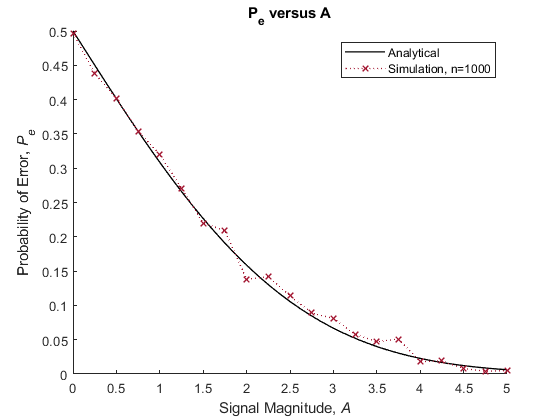

fig1 = figure; % Create a new figure
hold on
% Plot the analytical solution
fplot(P_e_analytical, '-', 'Color', [0 0 0] ...
                         , 'LineWidth', 1 ...
                         , "XRange", [0 5])

% Plot the simulation for n=100 
plot(A_values, P_e_simulation, ':', 'Color', [0.6350 0.0780 0.1840] ...
                                  , 'LineWidth', 1 ...
                                  , 'Marker', 'x')
hold off

% Label the graph appropriately
legend('Analytical', 'Simulation, n=1000')
title("P_e versus A")
xlabel("Signal Magnitude, {\itA}  ")
ylabel("Probability of Error, {\itP_e}")

shg % Show the Figure

From the plot above, we can see the the numerical and analytical solutions agree with one another. Though they do not align perfectly, increasing the sample size of the simulation will cause the numerical solution to converge upon the analytical solution. The sample size was chosen to demonstrate a subtle difference between solution methods and to distinguish on the figure.

From the trend, we can see that the probability of error,$P_e$, *decreases* for large values of $A$. This is expected due to the fact that if we increase the magnitude of the input the signal, the effect of the that the random Gaussian noise, $W$, has on the signal decreases. As the limit of the magnitude of the input signal approaches infinity, the probability of a error goes to zero,


$$\underset{A\to \infty \;}{\mathrm{lim}} P_e \left(A\right)=0$$


Another interesting feature of this plot is that the probability of error when $A$ is equal to zero approaches 0.5. At this point, the probability of error has the same distribution as the random variable, $W$, which is a Normal Guassian distribution (centered at 0 with a standard deviation of 1). Thus, without any input signal amplitude $A$, the PDF of the receiver becomes the same as the for a Normal Guassian variable (which is what $W$ is).

### 1.3 Discussion

With this information, we can analytically/numerically determine receiver gain values, $A$, such that the probability of error is limited. For example, let's design a signal such that the probablity of error $P_e$ does not exceed 0.01. That is, we can expect that we will only lose 1 bit of information for every 100 bits sent (assuming that we have a very large sample size). First, let's determine an solution using our analytical function. The problem constraint can be expressed by the following equation,


$$P_e \left(A\right)\le 0\ldotp 01$$


where $P_e \left(A\right)$ is our analytically determined solution to $P_e$ as a function of $A$. We then then substitute our equation,


$$\frac{1}{2}\left(1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right)\le 0\ldotp 01$$


then, multiplying both sides by 2


$$1-\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\le 0\ldotp 02$$


then, subtracting 1 from both sides while keeping $A$ on the left hand side,


$$\mathrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\le 0\ldotp 98$$


and taking the inverse error function of both sides,


$$\frac{\sqrt{2}}{4}A\le {\mathrm{erf}}^{-1} \left(0\ldotp 98\right)$$


isolating A to the left hand side of the equation


$$A\le 2\sqrt{2}{\mathrm{erf}}^{-1} \left(0\ldotp 98\right)$$


and finally, evaluting the inverse error function and square root for the numerical approximation,


$$A\ge 4\ldotp 653$$


A_min = vpa(solve(0.01 == P_e_analytical,A), 4) % Minimum value of A such P_e <= 0.01

$$A\_min = 4.653$$

Alternatively, we can also find the solution to this problem using our numerical simulation results. We can determine the value of $A$ such that $P_e \le 0\ldotp 01$ by finding the value at which $P_e \left(A\right)$ is equal to 0.01. That is, we can draw a horizontal line at $P_e =0\ldotp 01$ until we reach our function, and then draw a vertical line down to find $A_{\mathrm{min}}$. We zoom in on the plot and show this method graphically as follows,

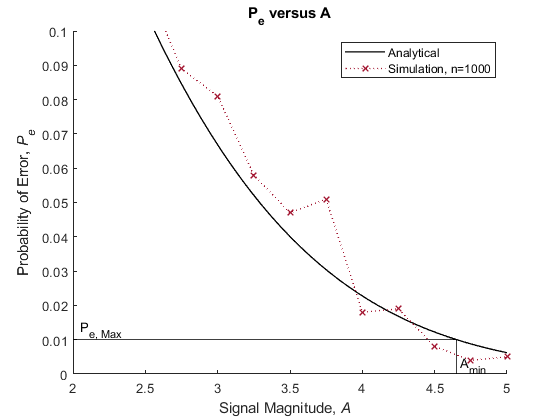

fig2 = fig1;
hold on
plot([double(A_min), double(A_min)], [0, 0.01], 'Color', [0 0 0])
plot([0, double(A_min)], [0.01 0.01], 'Color', [0 0 0])
text(2.05, 0.013, 'P_{e, Max}')
text(double(A_min)+0.02, 0.0025, 'A_{min}')
xlim([2 5])
ylim([0 0.1])
legend('Analytical', 'Simulation, n=1000')

Thus, it is very easy to see on the graph that at 0.01, the value of $A_{\mathrm{min}}$ is roughly equal to 4.6

## 2. COVID-19 Data Analysis

### 2.1 Background

In this exercise, we will analyze the data provided by [Our World in Data](https://github.com/owid/covid-19-data/tree/master/public/data) to understand the Coronavirus pandemic. In particular, we will study the factors that might impact the mortality rate of COVID-19. Our World in Data provides daily numbers on confirmed cases and deaths, testings, vaccinations, and other metrics for over 100 countries. For this study, consider the following data: *new_deaths_per_million* for the month of September 2021, *new_tests_per_thousand* for the same period, *people_vaccinated_per_hundred*, *aged_70_older*, *gdp_per_capita, cardiovasc_death_rate, diabetes_prevalence*. If a country misses any of the data, remove that country in this study.

- Plot the distribution of death rates for all countries. Compute the average death rates and the variance (Don’t use MATLAB built-in functions). What do these numbers tell us? Describe anything else you observe from the data.

- Study all other metrics. Plot their distributions, compute and interpret the average values and variances.

- Compute the correlation coefficients between the death rates and other metrics. What factor(s) affect the mortality rate the most? Plot the scatter diagram to support your argument. Describe anything else you observe from the data.

### Import and Filtering Data

First, we must import the most recent data from the file of comma separated variables.

raw_covid_data = readtable('owid-covid-data.csv'); % Table of raw covid data

Next, we can identify a list of unique country names

unique_countries = unique(raw_covid_data.location); % Unique country names

Now comes the tricky part. For this study, we reject all countries that miss any of the data. That is, each country must have a at least one distinct value for every random variable under consideration. To do this, we create an empty array which will contain the values of all unique countries that fit this rule. Next, check whether the country has at least one data point for every random variable. If the country does not contain an empty or null array of values for each random variable, we accept it and append it to a list of countries which fit this category.

countries = cell(1);
% Aquire data for each country with valid data
for k = 1:length(unique_countries)
    % Filter by month and valid values
    if or(isempty(raw_covid_data.new_deaths_per_million( ...
            ...
            string(raw_covid_data.location) == unique_countries(k) ...
                ...
                & raw_covid_data.date >= '1-Sep-2021' ...
                & raw_covid_data.date <= '30-Sep-2021')) ...
       , all(isnan(raw_covid_data.new_deaths_per_million( ...
            string(raw_covid_data.location) == unique_countries(k) ...
                & raw_covid_data.date >= '1-Sep-2021' ...
                & raw_covid_data.date <= '30-Sep-2021'))))
        continue
    % Filter by month and valid values                                    
    elseif or(isempty(raw_covid_data.new_tests_per_thousand(string(raw_covid_data.location) == unique_countries(k) ...
                                                     & raw_covid_data.date >= '1-Sep-2021' ...
                                                     & raw_covid_data.date <= '30-Sep-2021')) ...
           , all(isnan(raw_covid_data.new_tests_per_thousand(string(raw_covid_data.location) == unique_countries(k) ...
                                                     & raw_covid_data.date >= '1-Sep-2021' ...
                                                     & raw_covid_data.date <= '30-Sep-2021'))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.people_vaccinated_per_hundred( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.people_vaccinated_per_hundred( ...
                string(raw_covid_data.location) == unique_countries(k))))
       continue 
    % Filter by valid values   
    elseif or(isempty(raw_covid_data.aged_70_older( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.aged_70_older( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values    
    elseif or(isempty(raw_covid_data.gdp_per_capita( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.gdp_per_capita( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.cardiovasc_death_rate( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.cardiovasc_death_rate( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.diabetes_prevalence( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.diabetes_prevalence( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    end
    % Append country name to list of countries with valid data
    countries(end+1,1) = unique_countries(k);
end
countries = string(countries(2:end)); % Remove the first, null index

Now, we have a list of countries which contain data for each random variable under consideration.

### 2.1 Distributions of Random Variables

Before we plot the distribution of death rates for all countries, we first determine the distribution of death rates for each country. For each country, we take the *average* death rates per million people. This gives us a distribution of average death rates per million people per country. Subsequently, the average value value of death rates per country is equal to the total average death rates.

Since we will be aquiring the distribution of other random variables, we can condense the collection of these distribution into a single **for** loop. First, we initialize empty arrays for each variable which are the lengths of the number of country. Thus, the total collection of variables per country makes up our distribution of random variables.

% Distributions of random variables
dist_avg_deaths_per_million = zeros(length(countries), 1);
dist_avg_tests_per_thousand = zeros(length(countries), 1);
dist_people_vaccinated_per_hundred = zeros(length(countries), 1);
dist_avg_aged_70_older = zeros(length(countries), 1);
dist_avg_gdp_per_capita = zeros(length(countries), 1);
dist_avg_cardiovasc_death_rate = zeros(length(countries), 1);
dist_avg_diabetes_prevalence = zeros(length(countries), 1);

One important point to note is that we will be computing the average (expected) value of *each* random variable for each country.

for k = 1:length(countries)
    new_deaths_per_million = raw_covid_data.new_deaths_per_million( ...
                                string(raw_covid_data.location) == countries(k) ...
                                & raw_covid_data.date >= '1-Sep-2021' ...
                                & raw_covid_data.date <= '30-Sep-2021' ...
                                & ~isnan(raw_covid_data.new_deaths_per_million));
                                        
    new_tests_per_thousand = raw_covid_data.new_tests_per_thousand( ...
                                string(raw_covid_data.location) == countries(k) ...
                                & raw_covid_data.date >= '1-Sep-2021' ...
                                & raw_covid_data.date <= '30-Sep-2021' ...
                                & ~isnan(raw_covid_data.new_tests_per_thousand));
                            
    dist_people_vaccinated_per_hundred(k) = max(raw_covid_data.people_vaccinated_per_hundred( ...
                                         string(raw_covid_data.location) == countries(k) ...
                                         & ~isnan(raw_covid_data.people_vaccinated_per_hundred)));
     
    aged_70_older = raw_covid_data.aged_70_older( ...
                    string(raw_covid_data.location) == countries(k) ...
                    & ~isnan(raw_covid_data.aged_70_older));
                                
    gdp_per_capita = raw_covid_data.gdp_per_capita( ...
                     string(raw_covid_data.location) == countries(k) ...
                     & ~isnan(raw_covid_data.gdp_per_capita));
    
    cardiovasc_death_rate = raw_covid_data.cardiovasc_death_rate( ...
                            string(raw_covid_data.location) == countries(k) ...
                            & ~isnan(raw_covid_data.cardiovasc_death_rate));
    
    diabetes_prevalence = raw_covid_data.diabetes_prevalence( ...
                          string(raw_covid_data.location) == countries(k) ...
                          & ~isnan(raw_covid_data.diabetes_prevalence));
    
    
    dist_avg_deaths_per_million(k) = first_moment(new_deaths_per_million);
    dist_avg_tests_per_thousand(k) = first_moment(new_tests_per_thousand);
    dist_avg_aged_70_older(k) = first_moment(aged_70_older);
    dist_avg_gdp_per_capita(k) = first_moment(gdp_per_capita);
    dist_avg_cardiovasc_death_rate(k) = first_moment(cardiovasc_death_rate);
    dist_avg_diabetes_prevalence(k) = first_moment(diabetes_prevalence);
end

distributions = [dist_avg_deaths_per_million, dist_avg_tests_per_thousand, dist_people_vaccinated_per_hundred, ...
                 dist_avg_aged_70_older, dist_avg_gdp_per_capita, dist_avg_cardiovasc_death_rate, dist_avg_diabetes_prevalence];
random_variable_names = {'Avg. New Deaths per Million', 'Avg. New Tests per Thousand', 'People Vaccinated Per Hundred', ...
                         'Avg. Aged 70 or Older', 'Avg. GDP per Capita', 'Avg. Cardiocascular Death Rate', 'Avg. Diabetes Prevalence'};
                     
table_distributions = array2table(distributions, 'RowNames',countries, ...
                                     'VariableNames', random_variable_names)

table_distributions = 97×7 table
                              Avg. New Deaths per Million    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiocascular Death Rate    Avg. Diabetes Prevalence
                              ___________________________    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

    Argentina                            2.4609                        0.60317                          65.36                        7.441                   18934                       191.03                           5.5          
    Arm

### 2.2 Analysis of Distribution of Death Rates

fig3 = figure

fig3 =   Figure (172) with properties:

      Number: 172
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


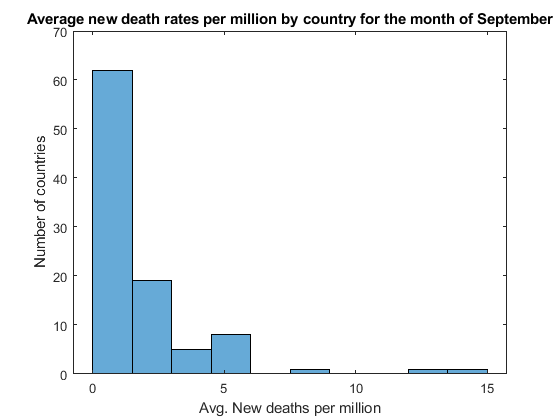

histogram(dist_avg_deaths_per_million, round(sqrt(length(countries))))
title('Average new death rates per million by country for the month of September')
ylabel('Number of countries')
xlabel('Avg. New deaths per million')

### 2.3 Analysis of Distributions of Other Random Variables

fig4 = figure

fig4 =   Figure (173) with properties:

      Number: 173
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


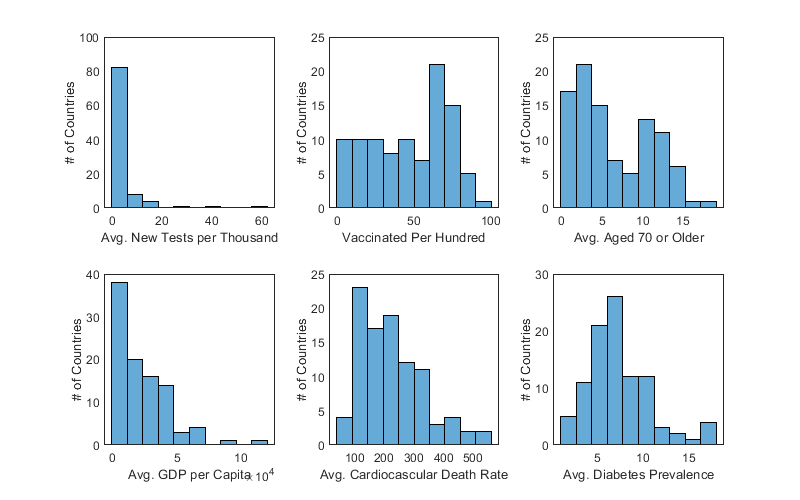

set(gcf, 'position', [0 0 800 500])
subplot(2, 3, 1)
histogram(table_distributions.("Avg. New Tests per Thousand"), round(sqrt(length(countries))))
xlabel('Avg. New Tests per Thousand')
ylabel('# of Countries')
subplot(2, 3, 2)
histogram(table_distributions.("People Vaccinated Per Hundred"), round(sqrt(length(countries))))
xlabel('Vaccinated Per Hundred')
ylabel('# of Countries')
subplot(2, 3, 3)
histogram(table_distributions.("Avg. Aged 70 or Older"), round(sqrt(length(countries))))
xlabel('Avg. Aged 70 or Older')
ylabel('# of Countries')
subplot(2, 3, 4)
histogram(table_distributions.("Avg. GDP per Capita"), round(sqrt(length(countries))))
xlabel('Avg. GDP per Capita')
ylabel('# of Countries')
subplot(2, 3, 5)
histogram(table_distributions.("Avg. Cardiocascular Death Rate"), round(sqrt(length(countries))))
xlabel('Avg. Cardiocascular Death Rate')
ylabel('# of Countries')
subplot(2, 3, 6)
histogram(table_distributions.("Avg. Diabetes Prevalence"), round(sqrt(length(countries))))
xlabel('Avg. Diabetes Prevalence')
ylabel('# of Countries')

table_averages = array2table(first_moment(table_distributions), 'RowNames', {'Global Average'}, ...
                                                                'VariableNames', random_variable_names)

table_averages = 1×7 table
                      Avg. New Deaths per Million    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiocascular Death Rate    Avg. Diabetes Prevalence
                      ___________________________    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

    Global Average              1.8016                         4.1216                          47.014                       6.5844                   23753                       225.08                         7.4159         


table_variences = array2table(second_moment(table_distributions), 'RowNames', {'Global Varience'}, ...
                                                            'VariableNames', random_variable_names)

table_variences = 1×7 table
                       Avg. New Deaths per Million    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiocascular Death Rate    Avg. Diabetes Prevalence
                       ___________________________    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

    Global Varience              5.9724                          67.08                          643.67                       20.626                4.3923e+08                     11509                          10.988         
